# Trim, Linearise and design a Control system for the ***Lagrangian*** quadcopter and **PENDULUM** model:

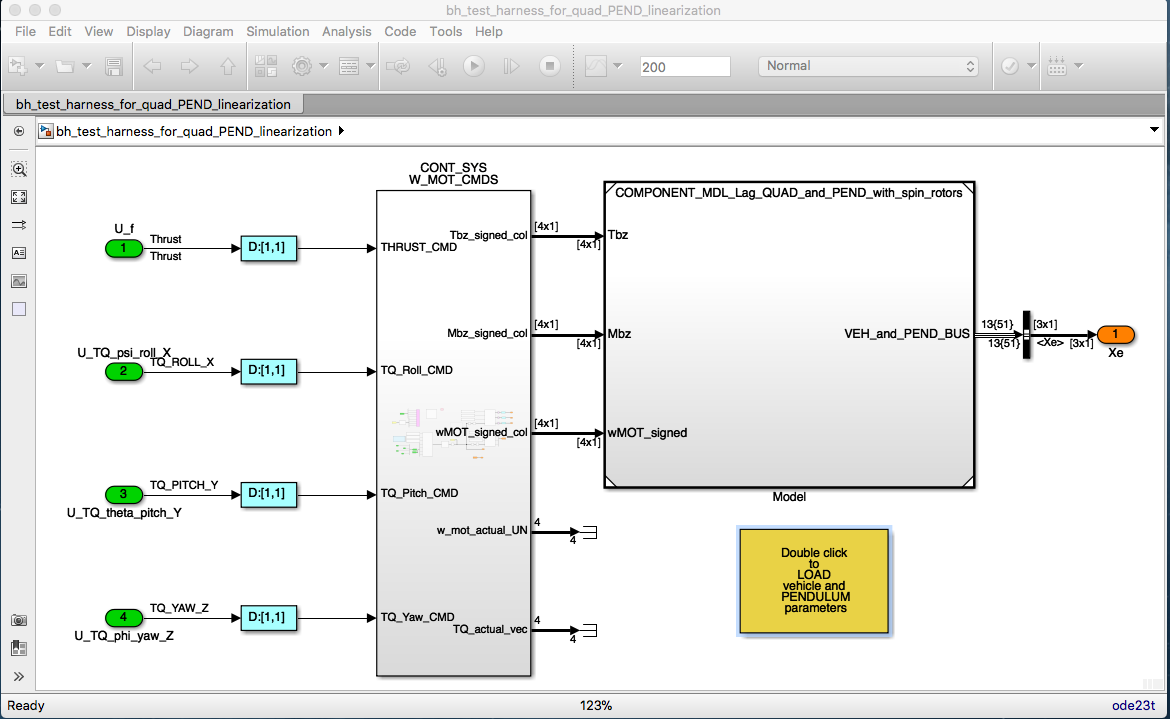

In this task we're going to linearise our **Simulink** quadcopter model. We're going to do this because we'd like to apply some "state space" control design techniques in order to design a control system for the quadcopter.  And as you know, these control techniques require a LINEAR plant model.  The workflow that we'll follow is this:

- We'll find an operating point for the pendulum. An operating point is characterized by the state(X), the input(U) and the output(Y).    We'll look specifically for an operating point that corresponds to steady state, ie: where the pendulum's state derivatives are ZERO. This is referred to as finding a **TRIMMED operating point**.

- We'll then use this TRIMMED operating point to calculate a **linearised** version of the quadcopter model.

- Finally, we'll then use this linearised model to design a full state feedback control system using the Linear Quadratic Integrator (LQI) technique.

`Bradley Horton : 18-Sept-2020, bradley.horton@mathworks.com.au  (updated for R2020b)`

# 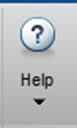 Take a moment !

If you're interested in reading about how to linearize a NON linear plant model.  Use the MATLAB HELP browser and try this simple text search

- `linearize control system`

HINT:  today we'll be using the functions:

- `operspec,   findop,   linearize`

## Load the model parameters:

bh_quad_params
bh_pend_params
bh_create_veh_and_pend_BUS

Just ensure that the the initial local Euler angles of the pendulum are ZERO:

P_pend.eul_loc_vec      = [0,0,0]'; % rad
P_veh_no_props.eul_init = [0,0,0]'; % rad

ANd echo the parameters that have been loaded into the workspace:

whos

  Name                   Size            Bytes  Class           Attributes

  PEND_BUS               1x1               311  Simulink.Bus              
  P_elec                 1x1               352  struct                    
  P_mot                  1x1              1232  struct                    
  P_mot_alone            1x1              1232  struct                    
  P_mot_vec              4x1              3584  struct                    
  P_one_prop             1x1               880  struct                    
  P_pend                 1x1               992  struct                    
  P_rot                  1x1               592  struct                    
  P_veh                  1x1              1536  struct                    
  P_veh_no_props         1x1              1536  struct                    
  VEH_AND_PEND_BUS       1x1               703  Simulink.Bus              
  XYZ_circ_mat          88x3              2112  double                    
  X_TS_OBJ              

warning('off')

## The name of the SIMULINK model that we'll linearise:

model  = 'bh_test_harness_for_quad_PEND_linearization';
open_system(model)

## Create the operating point specification object.

opspec = operspec(model);

Evaluating callback 'PostLoadFcn' for simulink
Callback: setsysloc_simulink(bdroot)
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating callback 'MaskParameterCallback' for bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_QUAD_and_PEND_with_spin_rotors/bh_6DOF_and_pend': ' '.


In our operating point specification, note the following:

- Our GREEN root level INPORT blocks are the system inputs 

- Our ORANGE root level OUTPORT blocks are the system outputs 

display(opspec)

opspec =  Operating point specification for the Model bh_test_harness_for_quad_PEND_linearization.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
    x    Known    SteadyState    Min     Max    dxMin    dxMax
    _    _____    ___________    ____    ___    _____    _____

(1.) DOT_phi
    0    false       true        -Inf    Inf    -Inf      Inf 
(2.) 

For each of our model states we can specify "desired" values for each of the following.  

- `x           :`   initial guess for state value

- `SteadyState :`   a logical indicating we are looking for a dx=0 final value

- `Min         :`   minimum bound for state value

- `Max         :`   maximum bound for state value

For our problem, we're going to look for an operating point where ALL of our states are at SteadyState (ie: dx/dt=0)

%[ opspec.States(1).SteadyState]
%[ arrayfun(@(a) (a.SteadyState), opspec.States) ].'

Our trimming function(coming up next) will then look for an operating point that satisfies this specification:

## Look for the steady state operating point.

opt           = findopOptions('DisplayReport','off');
[op,opreport] = findop(model,opspec, opt);

Evaluating callback 'MaskParameterCallback' for bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_QUAD_and_PEND_with_spin_rotors/bh_6DOF_and_pend': ' '.


Review our trimmed OPERATING point and NOTE the following:

- We have indeed found a steady state operating point because the state derivatives are either zero OR very small $O(10^{-7})$

- In this trimmed pose, ALL of the system outputs are ZERO.

- To maintain this trimmed pose we need to supply an INPUT force ... which is the force to counter gravity. 

display(opreport)

opreport =  Operating point search report for the Model bh_test_harness_for_quad_PEND_linearization.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
    Min               x              Max    dxMin             dx              dxMax
    ____    _____________________    ___    _____    _____________________    _____

(1.) DOT_phi
    -Inf                        0    Inf      0      -7.84584374501767e-29      0  
(2.) 

## Linearize the model about this operating point:

Next we'll linearise our model about this trimmed operating point:

my_LIN_PLANT = linearize(model,op);

Evaluating callback 'MaskParameterCallback' for bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_QUAD_and_PEND_with_spin_rotors/bh_6DOF_and_pend': ' '.


Note the names of the **INPUTS** "U"  

my_LIN_PLANT.InputName

ans = 4×1 cell array
    {'U_f'               }
    {'U_TQ_psi_roll_X'   }
    {'U_TQ_theta_pitch_Y'}
    {'U_TQ_phi_yaw_Z'    }


and the **OUTPUTS** "Y" 

my_LIN_PLANT.OutputName

ans = 3×1 cell array
    {'bh_test_harness_for_quad_PEND_linearization/Xe(1,1)'}
    {'bh_test_harness_for_quad_PEND_linearization/Xe(2,1)'}
    {'bh_test_harness_for_quad_PEND_linearization/Xe(3,1)'}


and the **STATES** "X"

my_LIN_PLANT.StateName

ans = 18×1 cell array
    {'DOT_phi'       }
    {'DOT_theta'     }
    {'DOT_psi'       }
    {'DOT_Xe'        }
    {'DOT_Ye'        }
    {'DOT_Ze'        }
    {'DOT_phi_pend'  }
    {'DOT_theta_pend'}
    {'DOT_psi_pend'  }
    {'phi'           }
    {'theta'         }
    {'psi'           }
    {'Xe'            }
    {'Ye'            }
    {'Ze'            }
    {'phi_pend'      }
    {'theta_pend'    }
    {'psi_pend'      }


And close the model:

close_system(model)

The state space matrix sizes are:

size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


## Check Controllability

Check if the linearised system is Full state Feedback(FSFB) Controllable. If the system is NOT FSFB controllable it means that we can NOT ***arbitrarily position*** the system poles.  We may still be able to position them to obtain a stable system  ... it's just that we can't arbitrarily position them.

A = my_LIN_PLANT.A;
B = my_LIN_PLANT.B;
C = my_LIN_PLANT.C;
D = my_LIN_PLANT.D;

co = ctrb(A,B);

if(rank(co) ~= size(A,1) )
    fprintf('\n ... ATTENTION: the system is NOT FSFB controllable');
    fprintf("\n ... rank(co) = %2d     and  size(A,1)=%2d", rank(co), size(A,1) );
end


 ... ATTENTION: the system is NOT FSFB controllable


 ... rank(co) = 14     and  size(A,1)=18

OK then, let's look at reducing the dimensionality of the model.   The [`balreal()`](matlab:  web(fullfile(docroot, 'control/ref/lti.balreal.html'))) function will compute a co-ordinate transformation for the state vector AND apply this to create a NEW system.   The [`balreal()`](matlab:  web(fullfile(docroot, 'control/ref/lti.balreal.html'))) function will also return the vector $\mathit{\mathbf{g}}$ corresponding to the diagonal of the transformed control grammian.  Small entries in $\mathit{\mathbf{g}}$ indicate states that can be removed to simplify the model

[sysb,g,T,Ti] = balreal(my_LIN_PLANT);


if( rank(ctrb(sysb)) ~= size(sysb.A,1) )
    fprintf('\n ... ATTENTION: the system is NOT FSFB controllable');
    fprintf("\n ... rank(sysb) = %2d     and  size(A,1)=%2d", rank(ctrb(sysb)), size(sysb.A,1) );
end


 ... ATTENTION: the system is NOT FSFB controllable


 ... rank(sysb) =  6     and  size(A,1)=18

And use the [`modred()`](matlab:  web(fullfile(docroot, 'control/ref/ss.modred.html'))) function to simplify(reduce) the system:

rsys     = modred(sysb, 7:18);
size(rsys)

State-space model with 3 outputs, 4 inputs, and 6 states.



[rank(ctrb(rsys)),  size(rsys.A,1) ] 

ans =      6     6


size(rsys)

State-space model with 3 outputs, 4 inputs, and 6 states.


## Control design:

We'll use the approach described by the LQI() function, ie::

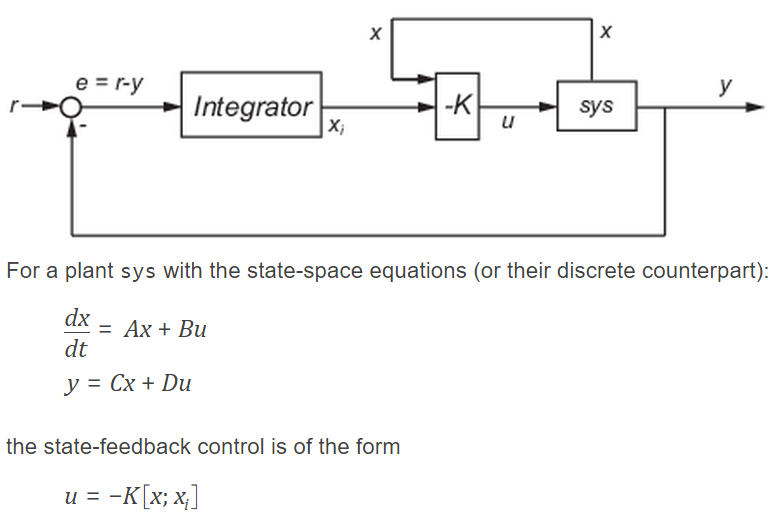

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


And the controller gain $K$ is found by minimizing the cost function:

- $J\left(u\right)=\int_0^{\infty } z^T \ldotp Q\ldotp z\;\;\;\;+\;\;\;\;u^T \ldotp R\ldotp u\;\;\;\;\;+\;\;\;\;\;2\ldotp z^T \ldotp N\ldotp u\;\;\;\mathrm{dt}$      where     $z=\left\lbrack \begin{array}{c}
x\\
x_i 
\end{array}\right\rbrack$

THE_SYS = rsys;

Nx      = size(THE_SYS.A,1);  
Nu      = size(THE_SYS.B,2);  
Ny      = size(THE_SYS.C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

kk_list              = 4.4e4:1e5;
res_T.kk_list        = kk_list(:);
res_T.kk_was_good_tf = false(length(kk_list),1);
res_T.e              = zeros(length(kk_list), (Nx+Ny));
for ii=1:length(kk_list)
    if(0==mod(ii,1000))
        fprintf("\n ... finished run %5d ", ii);
    end
    
    THE_KK     =  kk_list(ii);

    tmp        = [ones(1, Nx+Ny)];
    Q          = diag(tmp); 
    tmp        = THE_KK*[1,1,1,1];  
    R          = diag(tmp); 

    try
       [K,~,e] = lqi(THE_SYS,Q,R,[]);
       %fprintf('\n ... found one for kk=%5d', kk);
       res_T.kk_was_good_tf(ii) = true;
       res_T.e(ii,:) = e(:).';
    catch        
    end
end


 ... finished run  1000 
 ... finished run  2000 
 ... finished run  3000 
 ... finished run  4000 
 ... finished run  5000 
 ... finished run  6000 
 ... finished run  7000 
 ... finished run  8000 
 ... finished run  9000 
 ... finished run 10000 
 ... finished run 11000 
 ... finished run 12000 
 ... finished run 13000 
 ... finished run 14000 
 ... finished run 15000 
 ... finished run 16000 
 ... finished run 17000 
 ... finished run 18000 
 ... finished run 19000 
 ... finished run 20000 
 ... finished run 21000 
 ... finished run 22000 
 ... finished run 23000 
 ... finished run 24000 
 ... finished run 25000 
 ... finished run 26000 
 ... finished run 27000 
 ... finished run 28000 
 ... finished run 29000 
 ... finished run 30000 
 ... finished run 31000 
 ... finished run 32000 
 ... finished run 33000 
 ... finished run 34000 
 ... finished run 35000 
 ... finished run 36000 
 ... finished run 37000 
 ... finished run 38000 
 ... finished run 39000 
 ... finished run 40000 

Interrogate the closed loop eigenvalues:

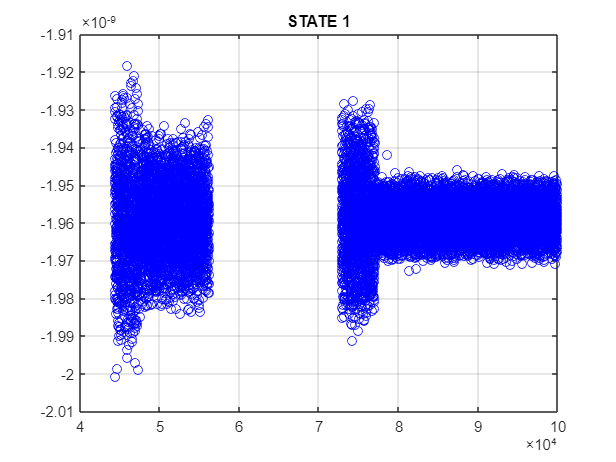

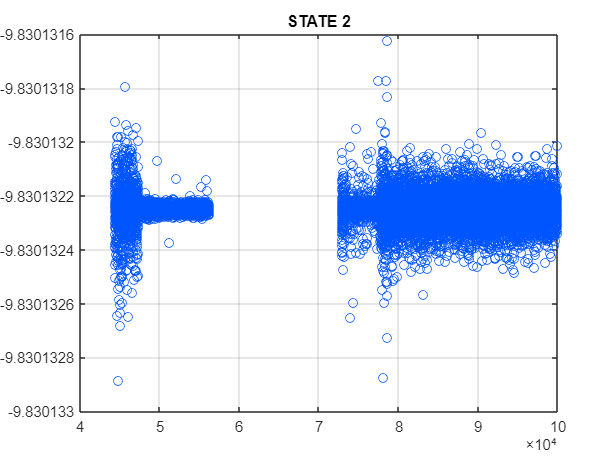

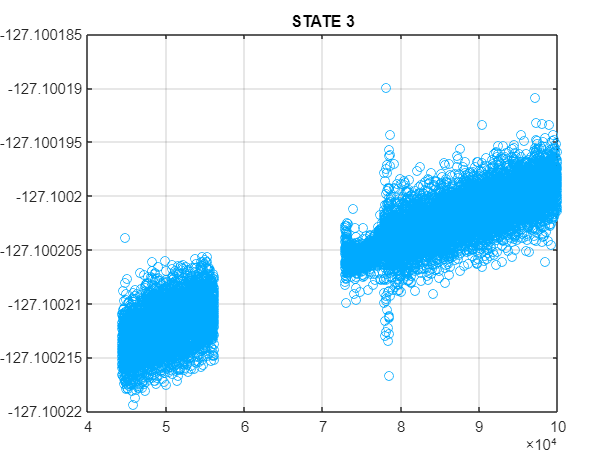

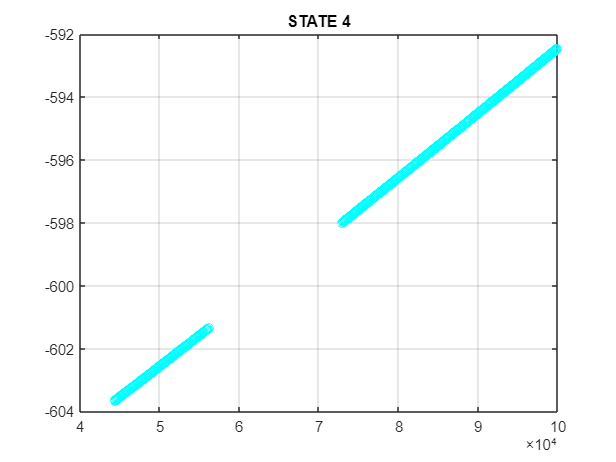

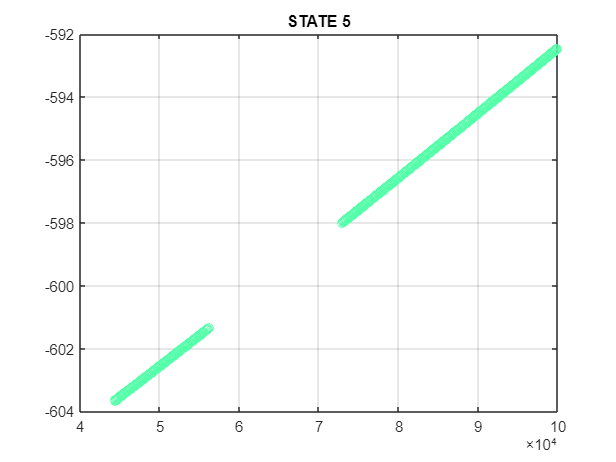

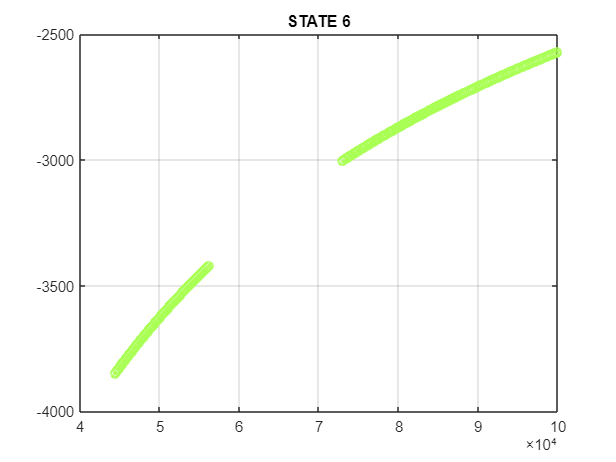

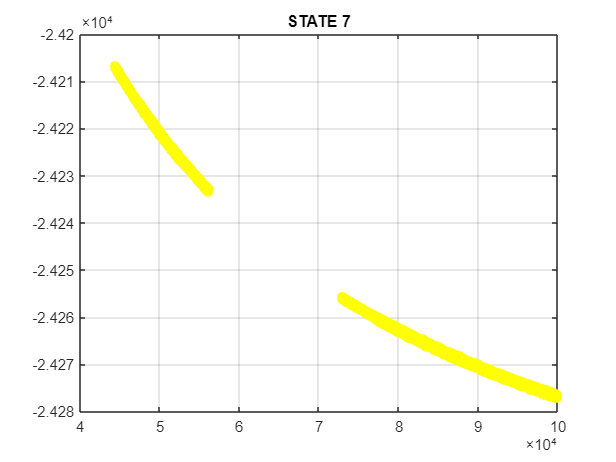

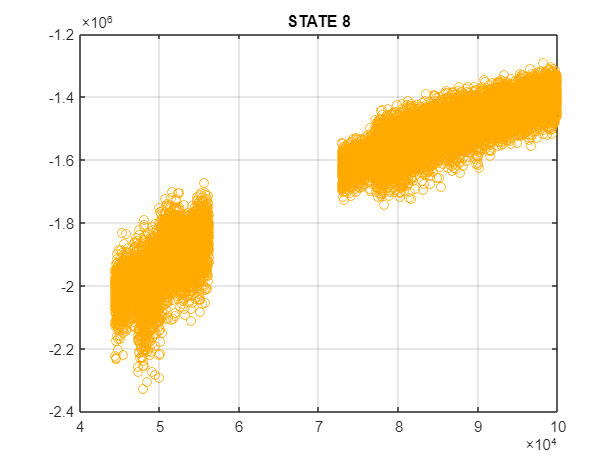

good_T = res_T;
good_T.kk_list = res_T.kk_list(res_T.kk_was_good_tf);
good_T.e       = res_T.e(res_T.kk_was_good_tf,:);

my_colors = jet(size(good_T.e,2));
for ff=1:size(good_T.e,2)
    figure;
    plot(good_T.kk_list,  real(good_T.e(:,ff)), 'o', "Color",my_colors(ff,:));  grid("on")
    title("STATE "+ff);
end

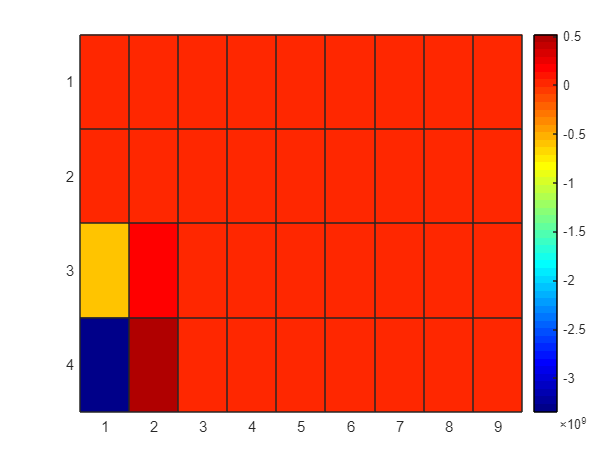


tmp        = [ones(1, Nx+Ny)];
Q          = diag(tmp); 
tmp        = good_T.kk_list(1)*[1,1,1,1];  
R          = diag(tmp); 
[K,~,e] = lqi(THE_SYS,Q,R,[]);

hfig = figure;
    heatmap(K,'Colormap', jet(50) );   

% clear res_T
% 
% kk_list              = [1e5:1e5:1e9];
% res_T.kk_list        = kk_list(:);
% res_T.kk_was_good_tf = false(length(kk_list),1);
% res_T.e              = zeros(length(kk_list), (Nx+Ny));
% for ii=1:length(kk_list)
%     if(0==mod(ii,1000))
%         fprintf("\n ... finished run %5d ", ii);
%     end
%     
%     THE_KK     =  kk_list(ii);
% 
%     tmp        = THE_KK*[ones(1, Nx+Ny)];
%     Q          = diag(tmp); 
%     tmp        = [1,1,1,1];  
%     R          = diag(tmp); 
% 
%     try
%        [K,~,e] = lqi(THE_SYS,Q,R,[]);
%        %fprintf('\n ... found one for kk=%5d', kk);
%        res_T.kk_was_good_tf(ii) = true;
%        res_T.e(ii,:) = e(:).';
%     catch        
%     end
% end
% 
% 
% figure;
% plot(res_T.kk_list, res_T.kk_was_good_tf, "or")